## Reading image

img = imread('Img-2.tif');

## Constants

img_size = size(img);
img_height = img_size(1);
img_width = img_size(2);

## Converting to fourier domain

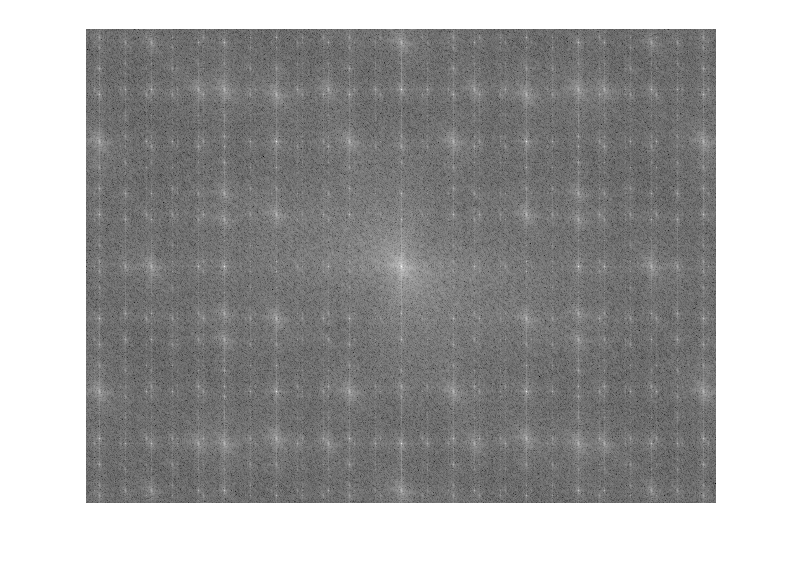

img_fourier = fft2(img);
img_fourier_shifted = fftshift(img_fourier);
% show_img(log(abs(img_fourier_shifted)), 'Fourier spectrum of img')
subplot(1,1,1);
imshow(log(abs(img_fourier_shifted)), []);

## Designing filter

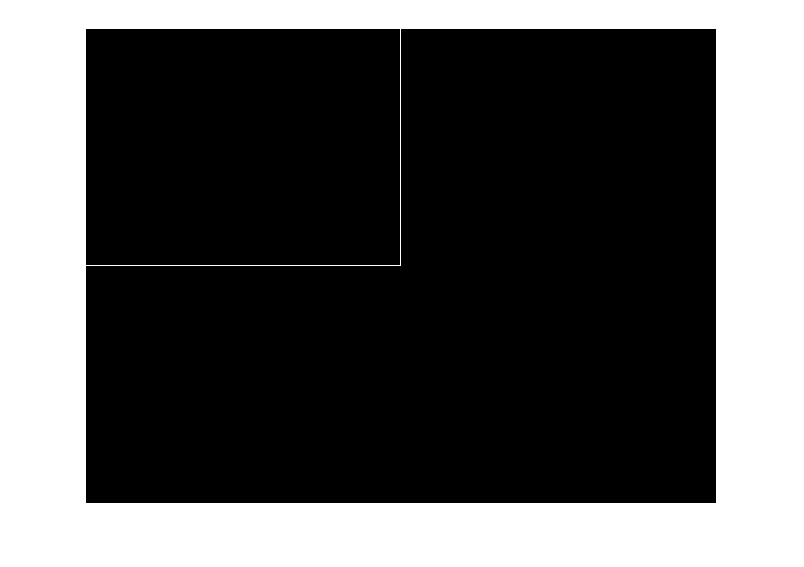

filter = zeros(img_size);

u_half = floor(img_height/2);
v_half = floor(img_width/2);

% (((u-u_half+notch_cntr_u)^2 + (v-v_half+notch_cntr_v)^2) >= (radius^2))
a = 5;
b = 5;
r = 5;

for u=1:img_height
    for v=1:img_width
        if (abs(a*(u-u_half)+b*(v-v_half) + abs(a*(u-u_half)-b*(v-v_half))) <= r)
            filter(u, v) = 1;
        end
    end
end

% filter = 1./(1+(notch_radius./filter).^(2*order));
% filter = 1 - filter;

% img_filtered = img_fourier_shifted .* filter;
% show_img(log(abs(img_filtered)), 'Filtered img');
imshow(log(abs(filter)), []);


% show_img(filter, 'Filter');

## Applying filter to image

img_filtered = img_fourier_shifted .* filter;
noise_pattern_fourier = img_fourier_shifted .* (1 - filter);

## Converting back to spatial domain

img_non_centered_filtered = ifftshift(img_filtered);
final_cleaned_img = abs(ifft2(img_non_centered_filtered));
noise_pattern_spatial_img = abs(ifft2(noise_pattern_fourier));
% show_img(abs(final_cleaned_img), 'Final img')

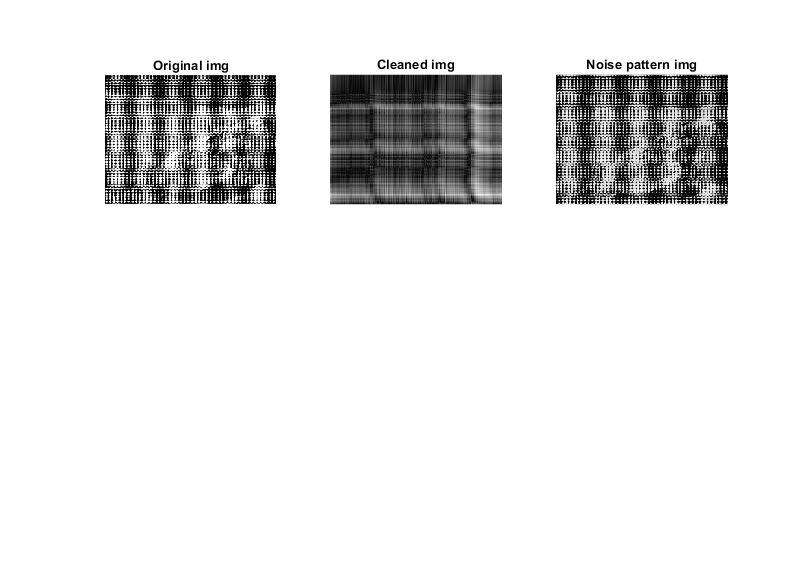

subplot(2, 3, 1); imshow(img, []); title('Original img');
subplot(2, 3, 2); imshow(final_cleaned_img, []); title('Cleaned img');
subplot(2, 3, 3); imshow(noise_pattern_spatial_img, []); title('Noise pattern img');